# **Лабораторная работа №2**

# **Дискретное преобразование Фурье.**

# **Амплитудный и фазовый спектры сигналов**

**Выполнил: Голев Андрей Дмитриевич, ИВТ-32.**

**Преподаватель: Лавриненко Александр Дмитриевич.**

# **Задача №1**

Требуется сформировать два синусоидальных сигнала с частотами $f_{01} =6\;\textrm{Гц}$ и $f_{02} =14\;\textrm{Гц}$ и начальными фазами $\varphi_{01} =\frac{3\cdot \pi \;}{4\;}\approx 2,3562$ и $\varphi_{02} =\frac{2\cdot \pi \;}{6\;}\approx 1,0472$. При этом длительность сигналов $T$ должна составлять $1\;с$, а частота дискретизации $f_s =64\;\textrm{Гц}$.

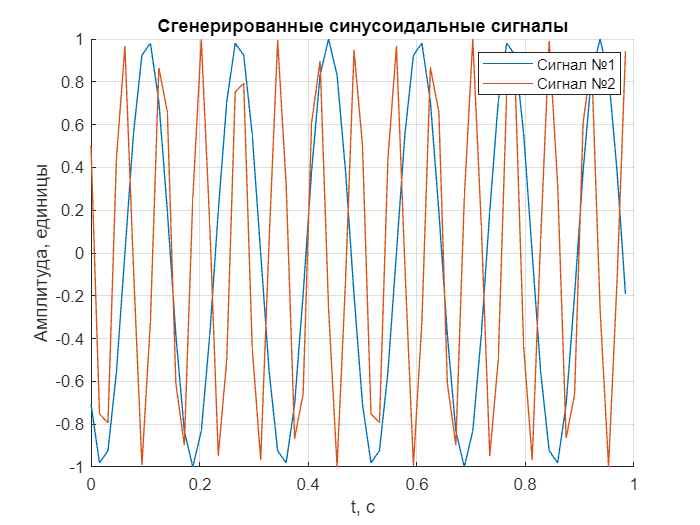

clc; clear; close all;
% Вариант №6, компьютер №14

f_01 = 6;
phase_01 = 3 * pi / 4;

f_02 = 14;
phase_02 = 2 * pi / 6;

f_s = 64;

t = ( 0 : 63 ) / f_s;

sig_1 = cos( 2 * pi * f_01 * t + phase_01 );
sig_2 = cos( 2 * pi * f_02 * t + phase_02 );

figure, hold on

plot( t, sig_1 )
plot( t, sig_2 )

title( "Сгенерированные синусоидальные сигналы" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

legend( "Сигнал №1", "Сигнал №2" )

grid on

Смешаем сгенерированные сигналы:

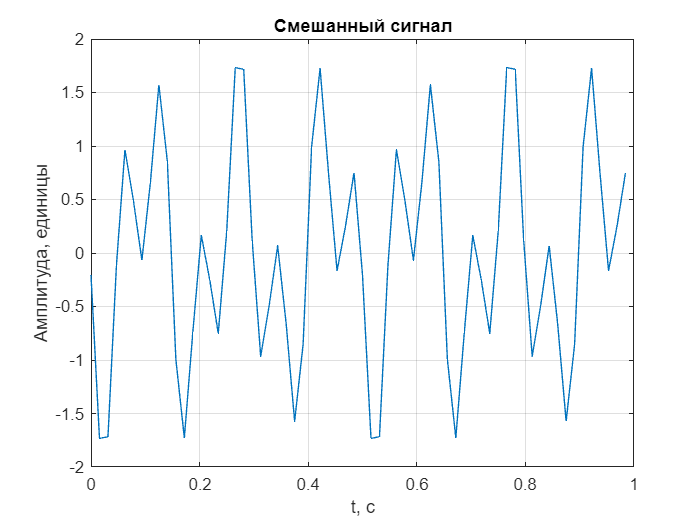

sig_sum = sig_1 + sig_2;

figure

plot( t, sig_sum )

title( "Смешанный сигнал" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

grid on

Вычислим дискретное преобразование Фурье для смеси сигналов с помощью функции **fft( f, fftk )**, где

- **f** - сигнал, подвергаемый преобразованию Фурье,

- **fftk** - количество точек в ДПФ, равное количеству точек входного сигнала.

Это необходимо для того, чтобы перевести сигнал из временной области в частотную.

Fourier_sum = fft( sig_sum, length( sig_sum ) );

В итоге получили вектор комплексных отчётов спектра.

Построим амплитудный спектр. Чтобы это сделать, необходимо взять модули комплексных чисел, делённых на количество точек. Поскольку частота дискретизации сама по себе равна количеству отсчётов за период, то высокочастотные составляющие не могут быть корректно отображены из-за эффекта Маура. Это приводит к тому, что вторая половина комплексных амплитуд является зеркальным отображением первой и не несёт дополнительной информации.

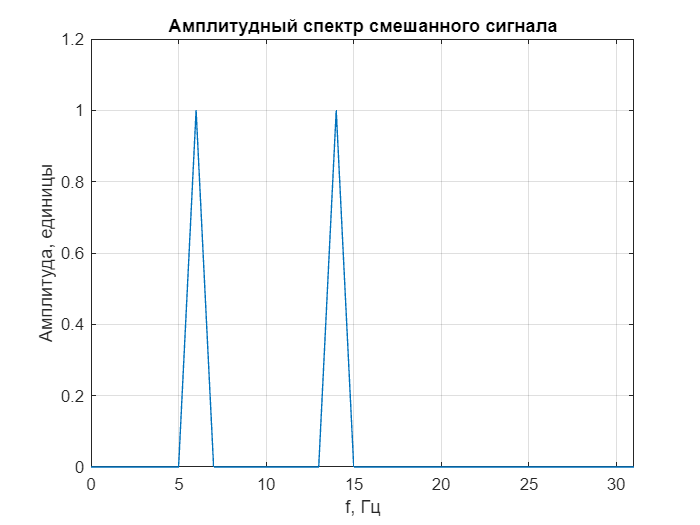

Amplitude_spectrum = 2 * abs( Fourier_sum / length( sig_sum ) )  ;

f = linspace( 0, f_s - 1, f_s );

figure

plot( f, Amplitude_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Амплитудный спектр смешанного сигнала" )
xlabel( "f, Гц" )
ylabel( "Амплитуда, единицы" )

grid on

Построим фазовый спектр сигнала, для чего необходимо взять аргументы комплексных чисел.

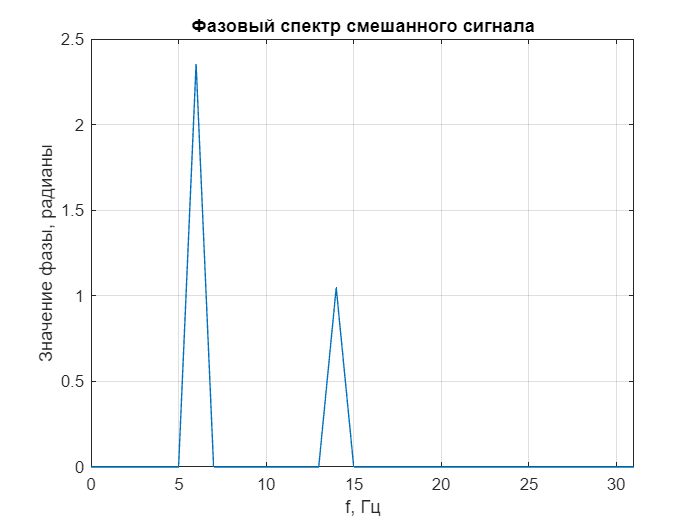

Fourier_sum ( abs( Fourier_sum ) < 1e-6 ) = 0;
Phase_spectrum = angle( Fourier_sum );

figure

plot( f, Phase_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Фазовый спектр смешанного сигнала" )
xlabel( "f, Гц" )
ylabel( "Значение фазы, радианы" )

grid on

Внесём в сумму сигналов шум удвоенной амплитуды сигналов

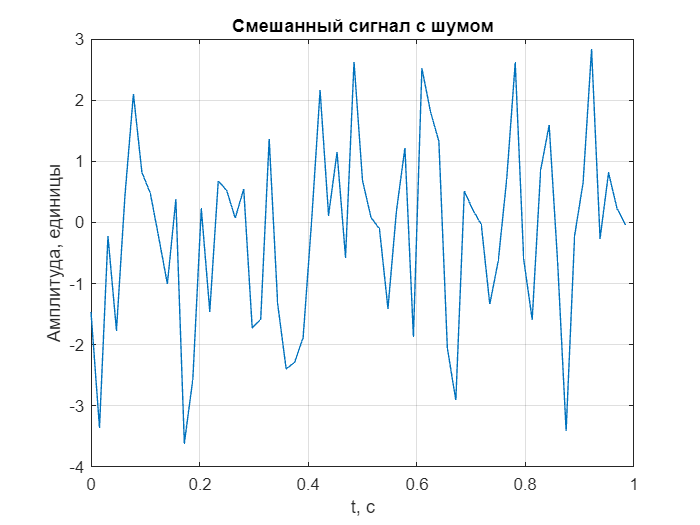

A_noise = 2;

Noise = A_noise - 2 * A_noise * rand( 1, f_s );

sig_noise = sig_sum + Noise;

figure

plot( t, sig_noise )

title( "Смешанный сигнал с шумом" )
xlabel( "t, c" )
ylabel( "Амплитуда, единицы" )

grid on

Рассчитаем спектры:

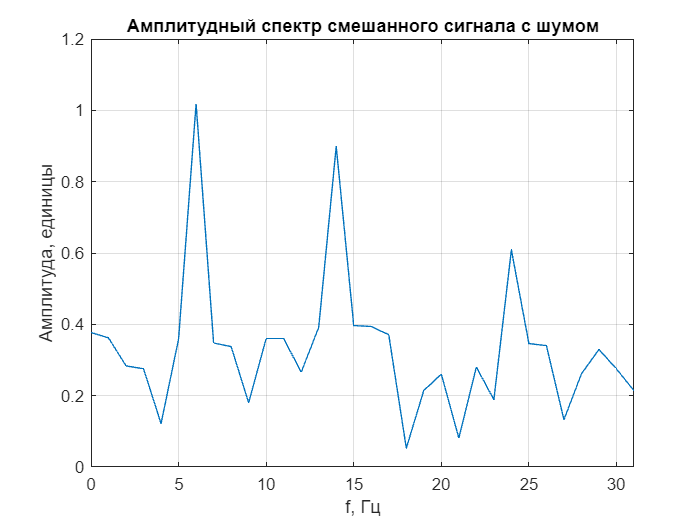

Fourier_noise = fft( sig_noise, length( sig_noise ) );

Amplitude_spectrum = 2 * abs( Fourier_noise ) / length( sig_noise )  ;

f = linspace( 0, f_s - 1, f_s );

figure

plot( f, Amplitude_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Амплитудный спектр смешанного сигнала с шумом" )
xlabel( "f, Гц" )
ylabel( "Амплитуда, единицы" )

grid on

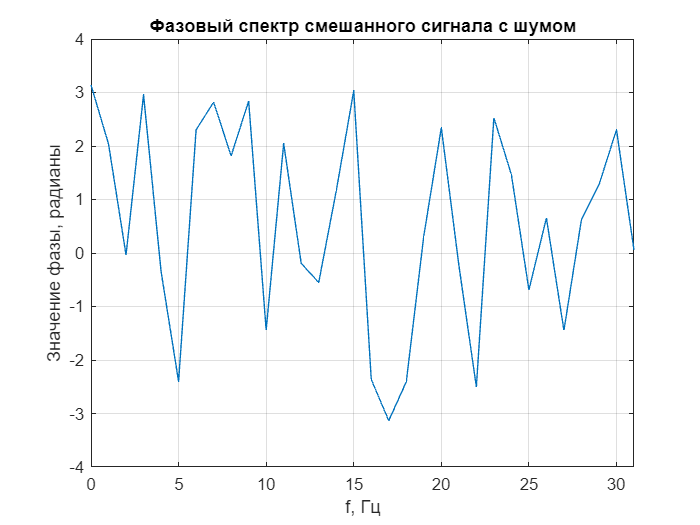


Fourier_noise ( abs( Fourier_noise ) < 1 ) = 0;
Phase_spectrum = angle( Fourier_noise );

figure

plot( f, Phase_spectrum )
xlim( [ 0, f_s / 2 - 1 ] )

title( "Фазовый спектр смешанного сигнала с шумом" )
xlabel( "f, Гц" )
ylabel( "Значение фазы, радианы" )

grid on

# **Задача №2**

## Исследование ДПФ комплексной вырезки гармонического сигнала

Требуется произвести расчёт спектров гармонического комплексного сигнала $\cos +j\cdot \sin$. Так как дискретное преобразование Фурье работает лишь с периодическими функциями, то для получения качественных спектральных характеристик вычисленияе ДПФ производится с большим периодом, чем длина исходного сигнала.

Будем предсказывать аналитически характеристики спектров для варианта задания, а затем сравним полученные теоретические результаты с результатами моделирования. 

**Выбор варианта:**

- ${\left(x_4 x_3 x_2 x_1 x_0 \right)}_2$- номер по списку в двоичном коде: ${00110}_2$;

- Длина исходного сигнала в отсчётах (должна быть нечётной) $N_и =N_{\textrm{код}} +10$: $N_и =14+10+1=25$;

- Частота исходного сигнала $f_0 =\left(1+{\left(x_1 x_0 \right)}_{2\to 10} \right)$: $f_0 =1+2=3\;\textrm{Гц}$;

- Начальная фаза исходного сигнала $\varphi_0 =\left(1+{\left(x_3 x_2 \right)}_{2\to 10} \right)\cdot \frac{\pi }{1+{\left(x_1 x_0 \right)}_{2\to 10} }$: $f_0 =\left(1+1\right)\cdot \frac{\pi }{1+2}=\frac{2\cdot \pi }{3}$;

- Длина периода вычисления ДПФ $N=128$;

- Период дискретизации $T=\frac{1}{3\cdot f_0 \cdot \left(1+{\left(x_3 x_2 x_1 \right)}_{2\to 10} \right)}$: $T=\frac{1}{3\cdot 3\cdot \left(1+3\right)}=\frac{1}{36}c$;

- Сдвиг исходного сигнала от центрального положения в отсчётах $\textrm{shift}=x_{3_{\textrm{знак}} } \cdot {\left(x_2 x_1 x_0 \right)}_{2\to 10}$: $\textrm{shift}=6$.

Тогда сигнал будет иметь вид $\dot{\textrm{sg}} \left(t\right)=\cos \left(2\cdot \pi \cdot f_0 \cdot t+\varphi_0 \right)+i\cdot \sin \left(2\cdot \pi \cdot f_0 \cdot t+\varphi_0 \right)=\cos \left(6\cdot \pi \cdot t+\frac{2\cdot \pi }{3}\right)+i\cdot \sin \left(6\cdot \pi \cdot t+\frac{2\cdot \pi }{3}\right)$.

**Рассчитаем параметры спектров:**

- Величину главного максимума амплитудного спектра $A=N_и =25$;

- Положение главного максимума амплитудного спектра $f^0 =f_0 \cdot T\cdot N\cdot \frac{1}{f_s }=3\cdot \frac{1}{36}\cdot 128\cdot \frac{1}{f_S }=\frac{32}{3}\cdot \frac{1}{f_s }\approx 10,67\cdot \frac{1}{f_s }$;

- Нули амплитудного спектра $f^1 =\frac{1}{t_и }=\frac{1}{T\cdot N_и }=\frac{N}{N_и }\cdot \frac{1}{f_s }=\frac{128}{25}\cdot \frac{1}{f_s }=5,12\cdot \frac{1}{f_s }$.

Рассчитаем наклон фазового спектра по 2-м произвольным точкам (A, B) фазового спектра в пределах главного максимума по формуле $\varphi \left(\mu \right)=\Delta \varphi \left(\mu \right)+\varphi_0 ,\;\Delta \varphi \left(\mu \right)=\mu \cdot \nu \cdot \frac{2\pi }{N}$, где $\nu =-\textrm{shift}$ - смещение центра сигнала от положения "равновесия" в отсчётах, а $\mu$ - номер отсчёта, для которого необходимо рассчитать значение фазового спектра (считается от точки главного максимума амплитудного спектра).  // Пока не сделано

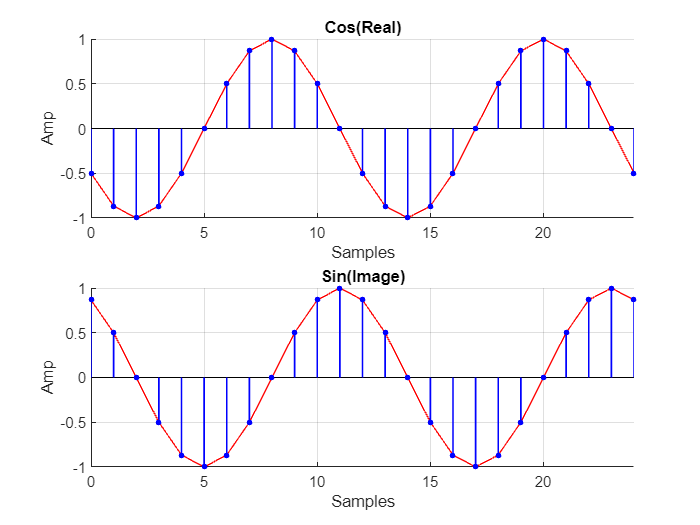

clc; clear; close all;

%%%%%%%Параметры сигнала%%%%%%%

N_i = 25;
T = 1 / 36;
f_s = 1 / T;
N = 128;
shift = 6;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n = 0 : N_i - 1;
t = ( 0 : f_s - 1 ) * T;

Real = cos( 6 * pi * t( 1 : N_i ) + 2 * pi / 3 );
Image = sin( 6 * pi * t( 1 : N_i ) + 2 * pi / 3 );

draw_sinc( N_i, n, Real, Image )

Для получения качественных спектральных характеристик необходимо дополнить сигнал защитными нулями до общей длины $N=128$.

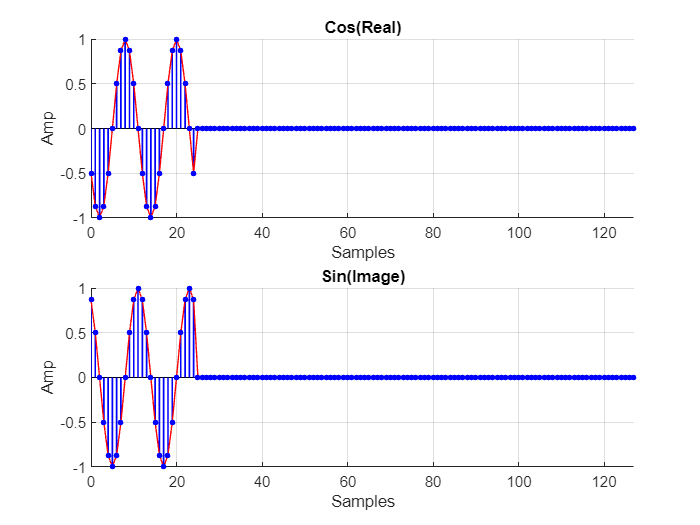

Real  = [ Real  zeros( 1, N - N_i ) ];
Image = [ Image zeros( 1, N - N_i ) ];

n = 0 : N - 1;

draw_sinc( N, n, Real, Image )

Сам же сигнал необходимо циклически сместить так, чтобы центральный отсчёт находился в точке $n=0$. 

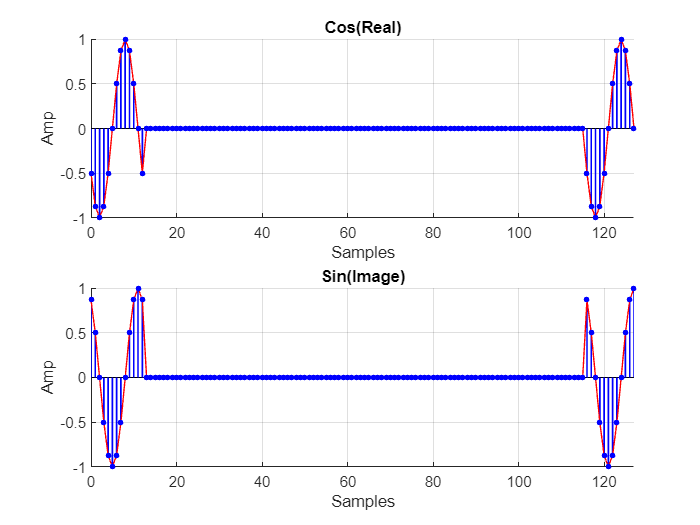

Real  = circshift( Real,  -( N_i - 1 ) / 2 );
Image = circshift( Image, -( N_i - 1 ) / 2 );

draw_sinc( N, n, Real, Image )

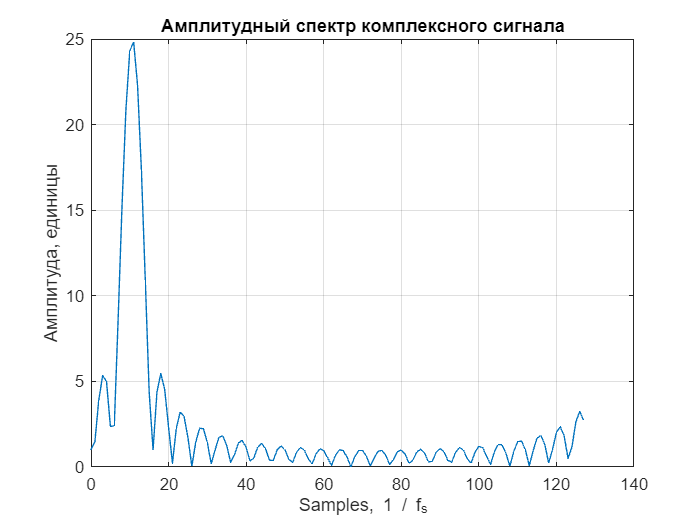

sig = Real + 1i * Image;

Fourier_sum = fft( sig, length( sig ) );

Amplitude_spectrum = abs( Fourier_sum );

f = linspace( 0, N - 1, N );

figure

plot( f, Amplitude_spectrum )

title( "Амплитудный спектр комплексного сигнала" )
xlabel( "Samples, 1 / f_s" )
ylabel( "Амплитуда, единицы" )

grid on

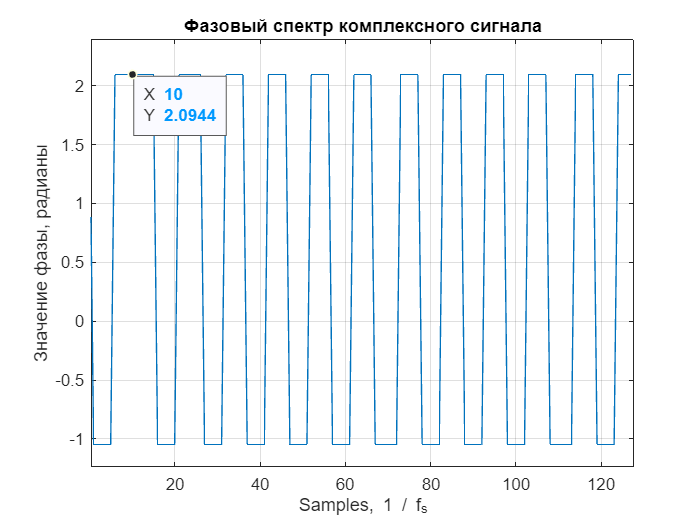

Phase_spectrum = angle( Fourier_sum );

figure

plot( f, Phase_spectrum )

title( "Фазовый спектр комплексного сигнала" )
xlabel( "Samples, 1 / f_s" )
ylabel( "Значение фазы, радианы" )

grid on

Произведём сдвиг сигнала по отсчётам:

Real  = circshift( Real,  ( N_i - 1 ) / 2 );
Image = circshift( Image, ( N_i - 1 ) / 2 );

draw_sinc( N, n, Real, Image )

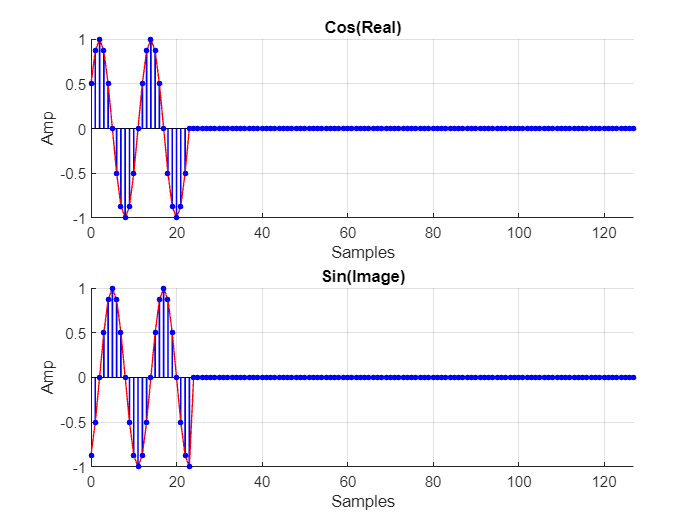

Real(N_i) = 0;
Image(N_i) = 0;

Real( 1 : N_i - 1 )  = circshift( Real( 1 : N_i - 1 ),  shift );
Image( 1 : N_i - 1 ) = circshift( Image( 1 : N_i - 1 ), shift );

draw_sinc( N, n, Real, Image )

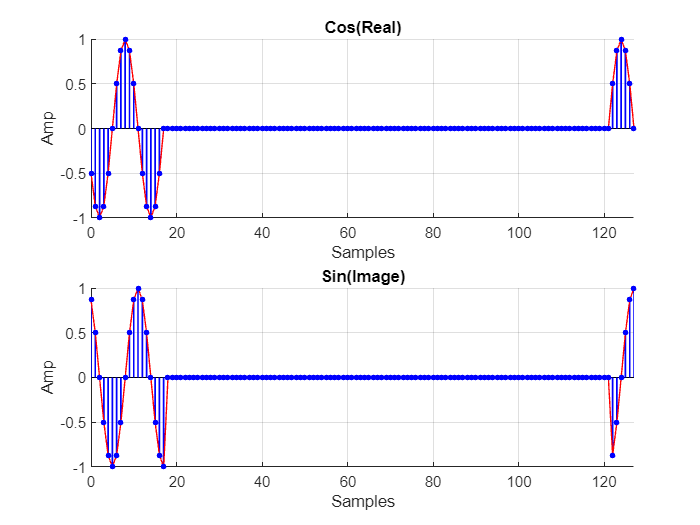

Real  = circshift( Real,  -( N_i - 1 ) / 2 + shift );
Image = circshift( Image, -( N_i - 1 ) / 2 + shift);
draw_sinc( N, n, Real, Image )

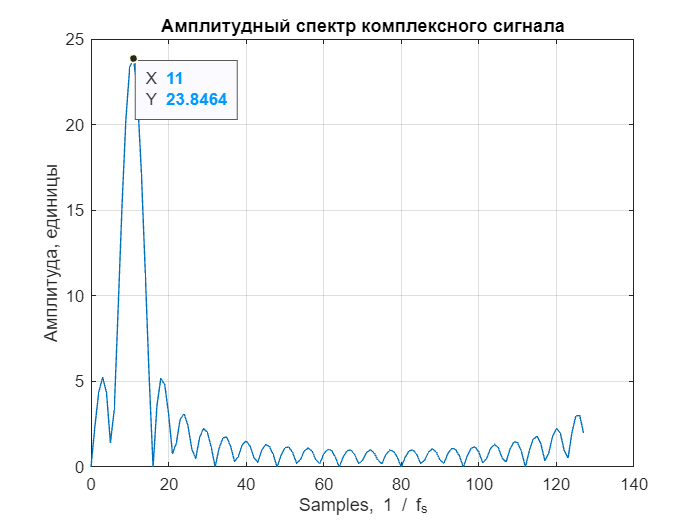

sig = Real + 1i * Image;

Fourier_sum = fft( sig, length( sig ) );

Amplitude_spectrum = abs( Fourier_sum );

f = linspace( 0, N - 1, N );

figure

plot( f, Amplitude_spectrum )

title( "Амплитудный спектр комплексного сигнала" )
xlabel( "Samples, 1 / f_s" )
ylabel( "Амплитуда, единицы" )

grid on

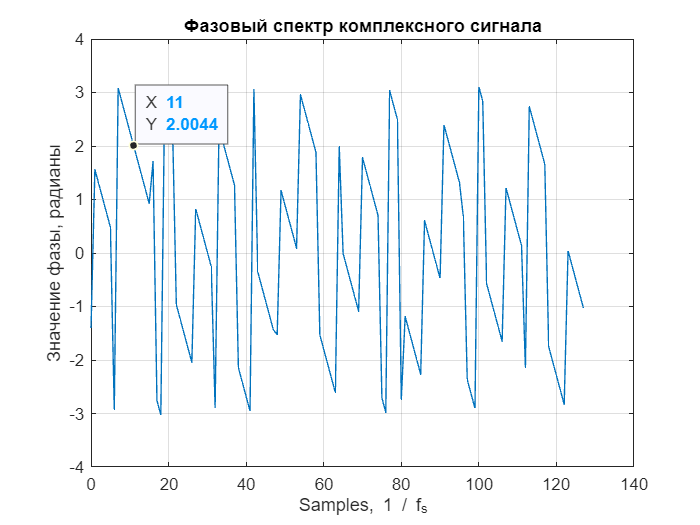

Phase_spectrum = angle( Fourier_sum );

figure

plot( f, Phase_spectrum )

title( "Фазовый спектр комплексного сигнала" )
xlabel( "Samples, 1 / f_s" )
ylabel( "Значение фазы, радианы" )

grid on